# Q2(a)

Initialize transfer function

s = tf('s');
G = [10*(s+2)/(s^2+0.2*s+100),1/(s+5);(s+2)/(s^2+0.1*s+10),5*(s+1)/((s+2)*(s+3))]

G =
 
  From input 1 to output...
           10 s + 20
   1:  -----------------
       s^2 + 0.2 s + 100
 
            s + 2
   2:  ----------------
       s^2 + 0.1 s + 10
 
  From input 2 to output...
         1
   1:  -----
       s + 5
 
          5 s + 5
   2:  -------------
       s^2 + 5 s + 6
 
Continuous-time transfer function.



Set the high frequency value to achieve the approximate desired loop shape

tau = 500000;

Calculating L

G_hat = inv(G,'min')/(1+s/tau);
L = [100/s 0;0 100/s];
K = L*G_hat;

l = G*K;

Performance plot of l(1,1)

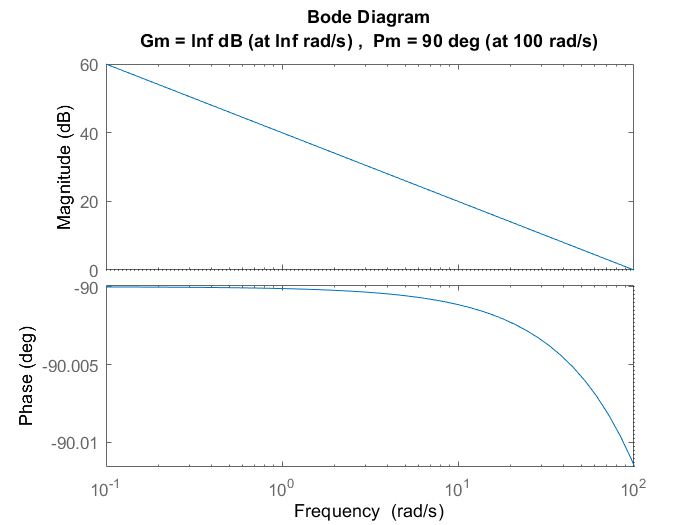

L11 = l(1,1);
margin(L11)

Sensitivity function magnitude bode plot

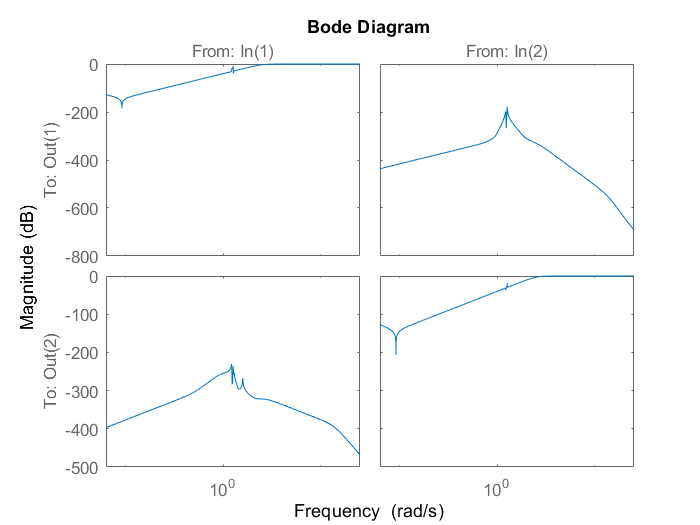

T = feedback(G*K,eye(2));
S = eye(2) - T;
bodemag(S)

# Q2(b)

Initialize parameters

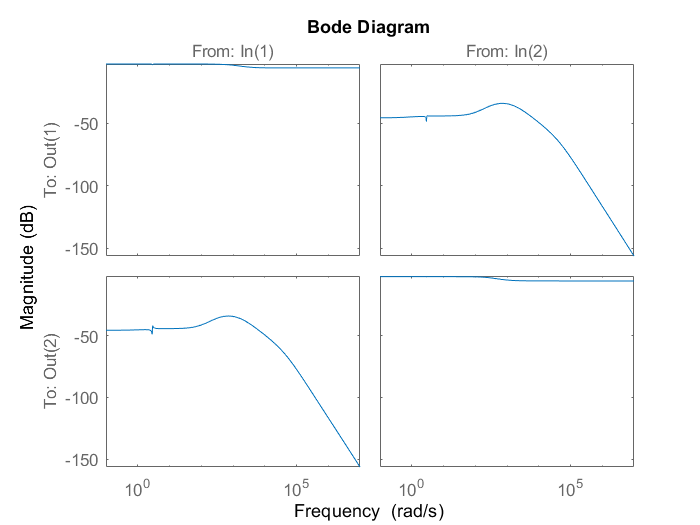

BW = 100;
Wu = [1/100 0;0 1/100];

% A while loop to maximize the bandwidth
while 1
    Wp = makeweight(1000,BW,1/2)*eye(2);
    Wt = makeweight(1/1.5,3*BW,1000)*eye(2);
    [K,CL,GAM,info] = mixsyn(G,Wp,Wu,Wt);
    if GAM>1
        break
    end
    BW = BW + 5;
end

% Computing the Sensitivity, Complementary Sensitivity, and the controller weight compensator
L = G*K;
T = feedback(L,eye(2));
S = eye(2) - T;

bodemag(Wp*S)

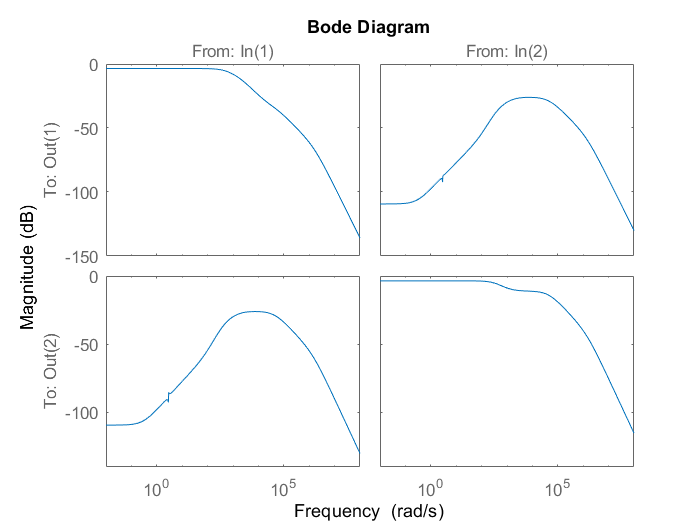

bodemag(Wt*T)

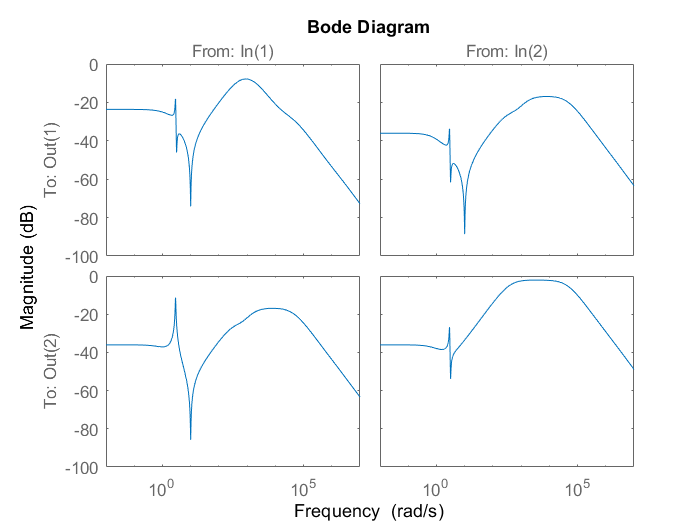

bodemag(Wu*K*S)

# Q3. (b)

Defining summing junctions

Sum1 = sumblk('V = w-y',2);
Sum2 = sumblk('yh = w-y',2);
s = tf('s');

Defining the transfer function blocks' inout and output signals

Wu = Wu*tf(1,1);
G.u = 'u';
G.y = 'y';

Wu.u = 'u';
Wu.y = 'z2';
Wp.u = 'yh';
Wp.y = 'z1';
Wt.u = 'y';
Wt.y = 'z3';

Connecting the blocks

P = connect(G,Wp,Wu,Wt,Sum1,Sum2,{'w','u'},{'z1','z2','z3','V'});

Perform hinfsyn for finding K

Kc = hinfsyn(P,2,2);

Plotting magnitude bode graph

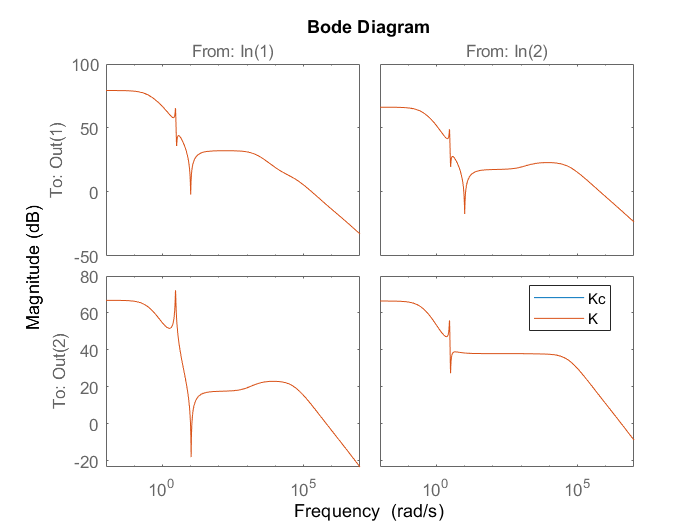

bodemag(Kc,K)
legend('Kc','K','Location',"best")

It can be observed that the controllers designed by both the methods are exactly equal and overlap each other on the magnitude bode plot.